# Deconvolution Benchmark: Matlab (deconSingle)

addpath("WBDeconvolution/")

## Test Image

%img = single(imread('ImagenPrueba.jpg'));
%psf = single(imread('psf.jpg'));

%output = DeconSingleView_fn(img,psf);

f = @() DeconSingleView_fn(img,psf); 

timeit(f)

## Cell

img = single(imread("cells3d_convolved.tif"));
psf = single(imread("cells3d_psf.tif"));

output2 = DeconSingleView_fn(img,psf);

f = @() DeconSingleView_fn(img,psf); 

timeit(f) % in seconds

## Cube of Spherical Beads

imgCube = tiffreadVolume('cubeConvolved.tif');
psfCube = tiffreadVolume('PSF.tif');

outputCube = DeconSingleView_fn(imgCube,psfCube);

f = @() DeconSingleView_fn(imgCube,psfCube); 
timeit(f) % in seconds

## _____________________________________________________________________

## C. Elegans embryo

function image_stack = load_image_stack(folder_path)
    % Listar todos los archivos en la carpeta y ordenar
    files = dir(fullfile(folder_path, '*.tif'));
    files = [files; dir(fullfile(folder_path, '*.png'))];
    files = [files; dir(fullfile(folder_path, '*.jpg'))];
    [~, index] = sort({files.name});
    files = files(index);
    
    % Leer la primera imagen para obtener las dimensiones
    first_image = imread(fullfile(folder_path, files(1).name));
    [height, width] = size(first_image);
    
    % Crear una matriz 3D vacía para almacenar las imágenes
    image_stack = zeros(height, width, length(files), 'single');
    
    % Leer el rango de valores para normalización
    max_val = double(max(first_image(:)));  % Valor máximo para normalización

    % Cargar cada imagen en la matriz 3D
    for i = 1:length(files)
        img = imread(fullfile(folder_path, files(i).name));
        % Convertir la imagen a single y normalizar
        image_stack(:, :, i) = single(img) / max_val;
    end
end


imageStack=ones(5,5);
imageStack(2,2)=2.5;
imageStack(3,3)=2.8;
imageStack(4,4)=2;
imageStack(2,3)=1.5;
imageStack(2,4)=2.5;
imageStack(3,2)=2.8

imageStack =    1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000
   1.000000000000000   2.500000000000000   1.500000000000000   2.500000000000000   1.000000000000000
   1.000000000000000   2.800000000000000   2.800000000000000   1.000000000000000   1.000000000000000
   1.000000000000000   1.000000000000000   1.000000000000000   2.000000000000000   1.000000000000000
   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000


psfStack=zeros(5,5);
psfStack(2:4,2:4)=1

psfStack =      0     0     0     0     0
     0     1     1     1     0
     0     1     1     1     0
     0     1     1     1     0
     0     0     0     0     0


deconvTEST = DeconSingleView_fn(imageStack,psfStack)

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


deconvTEST = 5×5 single matrix
   1.1154754   0.0625800   2.3689959   0.7772479   1.3308810
   2.1861596   2.3788834   3.1178761   0.3299666   0.0016944
   0.9417888   0.0404035   7.2669454   0.9548739   1.3335954
   1.2239373   2.5962880   0.7217221   1.4418467   0.0282861
   0.0071021   0.0010000   0.0010000   0.1136030   2.7579908


### Canal 1

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath1 = '/Users/yi/TFGNotebook/CElegans-CY3';
psfPath1 = '/Users/yi/TFGNotebook/PSF-CElegans-CY3';

% Cargar las imágenes en una matriz 3D
image_stack1 = load_image_stack(imagePath1);
psf_stack1 = load_image_stack(psfPath1);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack1 = image_stack1(1:356, 1:336, :);
psf_stack1 = psf_stack1(179:534,169:504, :);

%image_stack1 = image_stack1(1:356, 1:336, 52);
% Obtener las dimensiones de image_stack
disp(size(image_stack1))

   356   336   104



% Obtener las dimensiones de psf_stack
disp(size(psf_stack1))

   356   336   104



outputChannel1 = DeconSingleView_fn(image_stack1,psf_stack1);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


% Seleccionar el stack 52
stack_52 = outputChannel1(:,:,52)

stack_52 = 356×336 single matrix
   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000
   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0010000   0.0

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized = uint8(255 * mat2gray(stack_52)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
%imwrite(stack_52_normalized, '110long_iter_DeconSingleChannel1.png');

for i = 1:10
tic
resultado = DeconSingleView_fn(image_stack1,psf_stack1);
T(i) = toc
end

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000  14.736033292000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000  14.736033292000000  15.045771917000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000  14.736033292000000  15.045771917000000  15.206619125000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000  14.736033292000000  15.045771917000000  15.206619125000000  15.173150958000001


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000  14.736033292000000  15.045771917000000  15.206619125000000  15.173150958000001  15.321520832999999


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000  14.736033292000000  15.045771917000000  15.206619125000000  15.173150958000001  15.321520832999999  16.016354333999999


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000  14.736033292000000  15.045771917000000  15.206619125000000  15.173150958000001  15.321520832999999  16.016354333999999  16.456932291000001


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T =   14.967176917000000  14.721286291000000  14.736033292000000  15.045771917000000  15.206619125000000  15.173150958000001  15.321520832999999  16.016354333999999  16.456932291000001  15.408821334000001


f = @() DeconSingleView_fn(image_stack1,psf_stack1); 
T = timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T = 136.8016

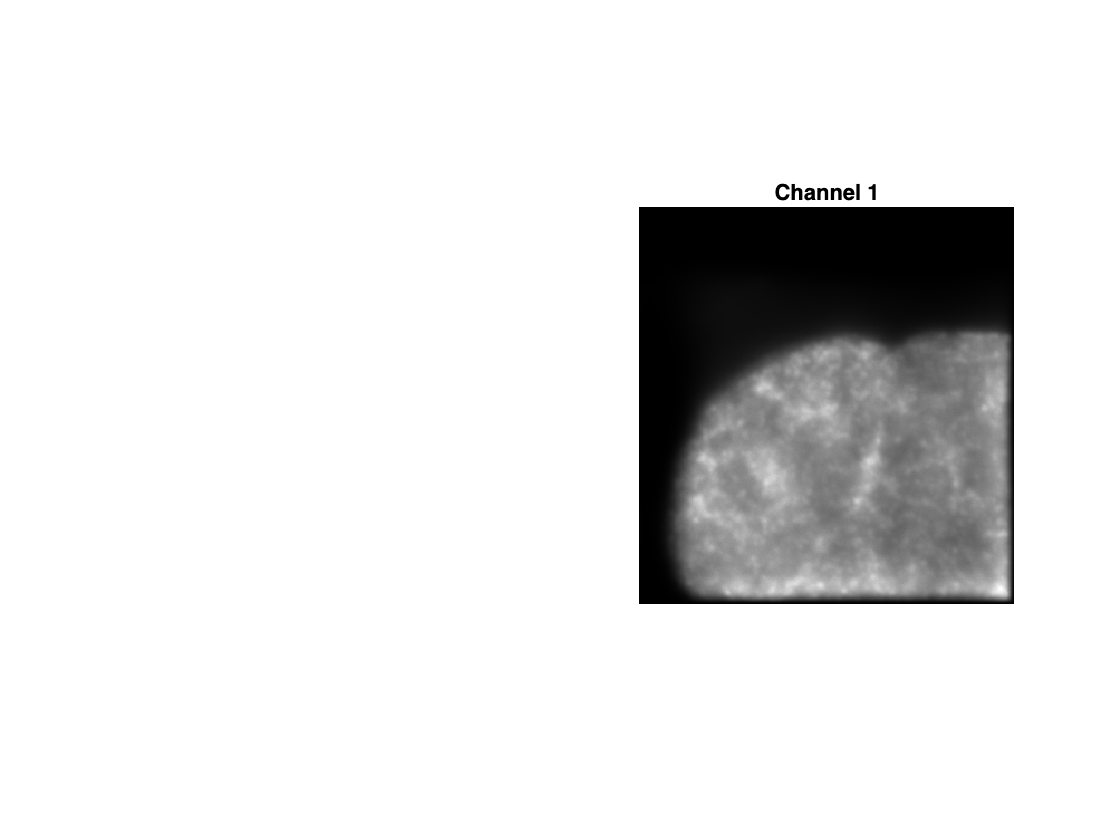

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(outputChannel1(:, :, 52),[]);

% Añadir título
title('Channel 1');

% Desactivar los ejes
axis off;

### Canal 2

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath2 = '/Users/yi/TFGNotebook/CElegans-DAPI';
psfPath2 = '/Users/yi/TFGNotebook/PSF-CElegans-DAPI';

% Cargar las imágenes en una matriz 3D
image_stack2 = load_image_stack(imagePath2);
psf_stack2 = load_image_stack(psfPath2);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack2 = image_stack2(1:356, 1:336, :);
psf_stack2 = psf_stack2(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack2));

   356   336   104



disp(size(psf_stack2));

   305   305   104



outputChannel2 = DeconSingleView_fn(image_stack2,psf_stack2);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


% Seleccionar el stack 52
stack_522 = outputChannel2(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized2 = uint8(255 * mat2gray(stack_522)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized2, '150iter_DeconSingleChannel2.png');

for i = 1:10
tic
resultado = DeconSingleView_fn(image_stack2,psf_stack2);
T3(i) = toc
end

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999  14.816320458000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999  14.816320458000000  15.165711957999999


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999  14.816320458000000  15.165711957999999  15.114897791000001


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999  14.816320458000000  15.165711957999999  15.114897791000001  16.119199915999999


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999  14.816320458000000  15.165711957999999  15.114897791000001  16.119199915999999  15.698560625000001


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999  14.816320458000000  15.165711957999999  15.114897791000001  16.119199915999999  15.698560625000001  15.983640375000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999  14.816320458000000  15.165711957999999  15.114897791000001  16.119199915999999  15.698560625000001  15.983640375000000  16.081910209000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T3 =   15.079376334000001  14.806448124999999  14.816320458000000  15.165711957999999  15.114897791000001  16.119199915999999  15.698560625000001  15.983640375000000  16.081910209000000  16.455264000000000


f = @() DeconSingleView_fn(image_stack2,psf_stack2); 
T = timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T = 171.4037

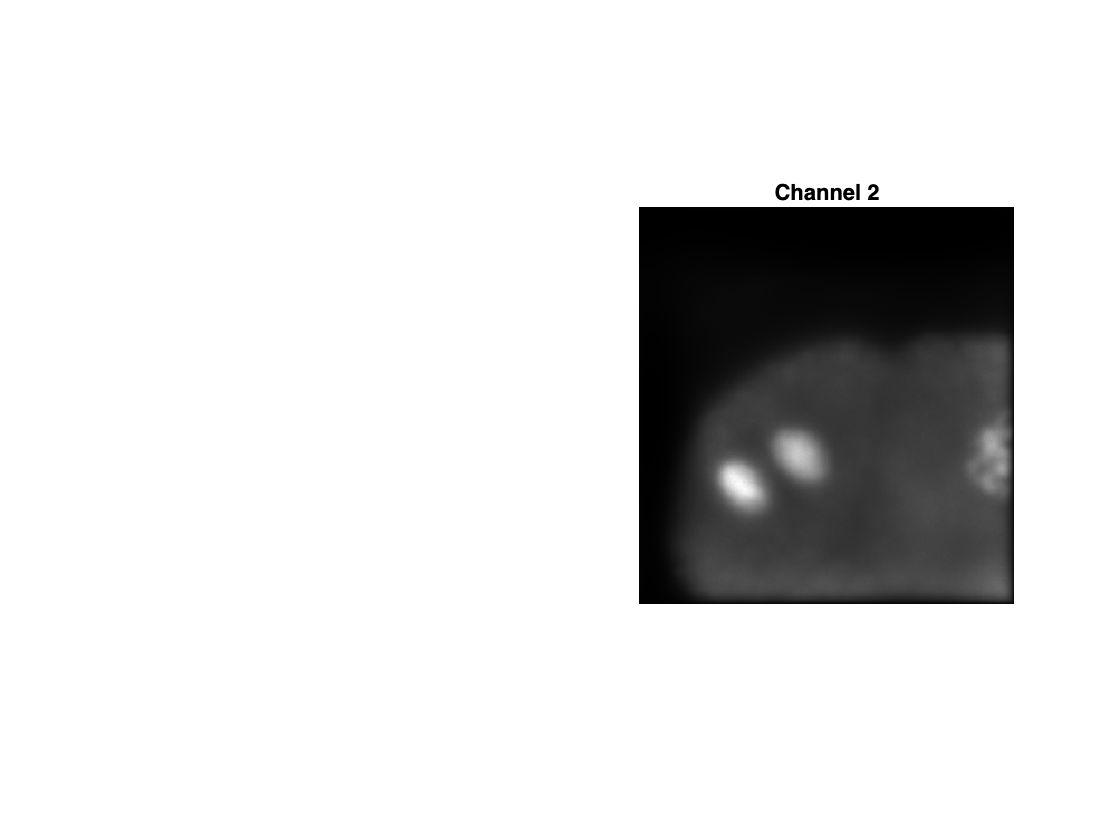

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(outputChannel2(:, :, 52),[]);

% Añadir título
title('Channel 2');

% Desactivar los ejes
axis off;

### Canal 3

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath3 = '/Users/yi/TFGNotebook/CElegans-FITC';
psfPath3 = '/Users/yi/TFGNotebook/PSF-CElegans-FITC';

% Cargar las imágenes en una matriz 3D
image_stack3 = load_image_stack(imagePath3);
psf_stack3 = load_image_stack(psfPath3);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack3 = image_stack3(1:356, 1:336, :);
psf_stack3 = psf_stack3(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack3));

   356   336   104



disp(size(psf_stack3));

   305   305   104



outputChannel3 = DeconSingleView_fn(image_stack3,psf_stack3);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


% Seleccionar el stack 52
stack_523 = outputChannel3(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized3 = uint8(255 * mat2gray(stack_523)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized3, '150iter_DeconSingleChannel3.png');

for i = 1:10
tic
resultado = DeconSingleView_fn(image_stack3,psf_stack3);
T2(i) = toc
end

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000  15.005922417000001


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000  15.005922417000001  15.656877416000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000  15.005922417000001  15.656877416000000  15.528567958000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000  15.005922417000001  15.656877416000000  15.528567958000000  15.525492500000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000  15.005922417000001  15.656877416000000  15.528567958000000  15.525492500000000  15.967536917000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000  15.005922417000001  15.656877416000000  15.528567958000000  15.525492500000000  15.967536917000000  15.972671833000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000  15.005922417000001  15.656877416000000  15.528567958000000  15.525492500000000  15.967536917000000  15.972671833000000  15.826672125000000


Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T2 =   14.621840457999999  14.770794917000000  15.005922417000001  15.656877416000000  15.528567958000000  15.525492500000000  15.967536917000000  15.972671833000000  15.826672125000000  15.888857666000000


f = @() DeconSingleView_fn(image_stack3,psf_stack3); 
T = timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T = 55.2331

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(outputChannel3(:, :, 52),[]);

% Añadir título
title('Channel 3');

% Desactivar los ejes
axis off;

### Combinación de canales

function normalized_image = normalize(image)
    min_val = double(min(image(:)));  % Convertir a double para evitar problemas con uint16
    max_val = double(max(image(:)));
    if min_val == max_val
        normalized_image = zeros(size(image), 'like', image);  % Usar el mismo tipo de datos
    else
        normalized_image = (double(image) - min_val) / (max_val - min_val);
    end
end

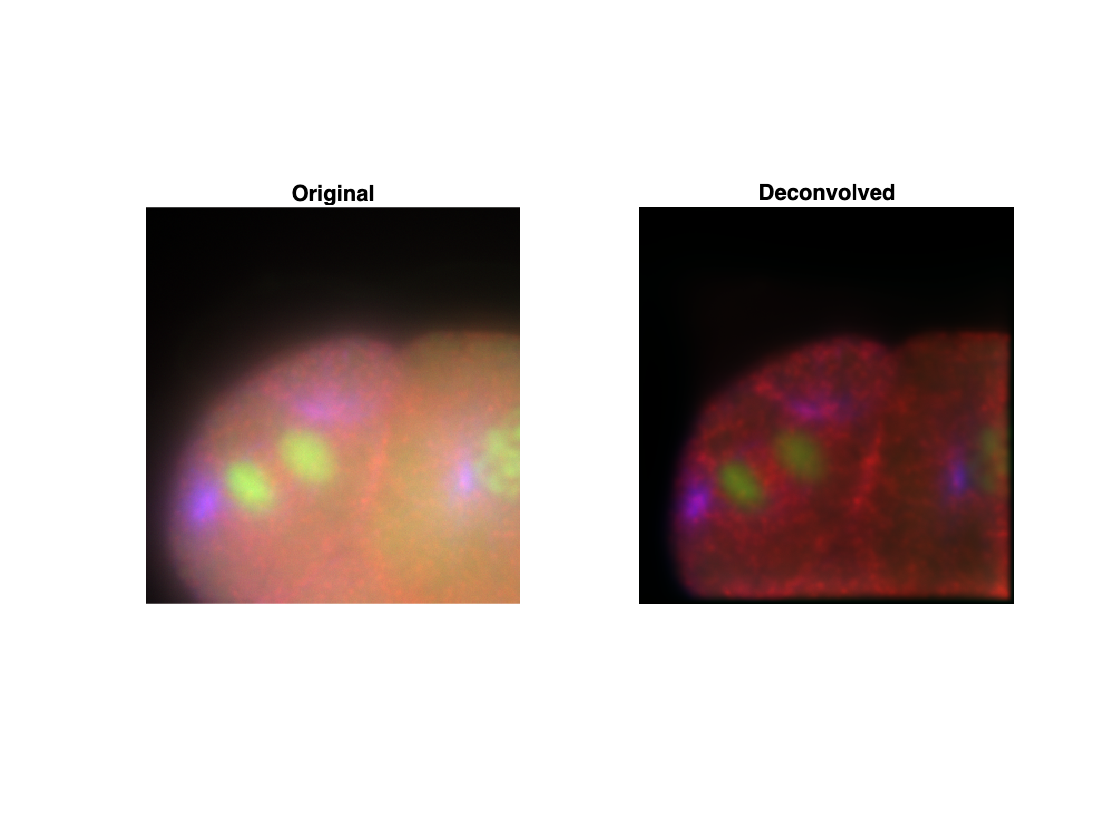


% Normalizar los canales (opcional, pero recomendado)
deconvolved_stack_R = normalize(outputChannel1);
deconvolved_stack_G = normalize(outputChannel2);
deconvolved_stack_B = normalize(outputChannel3);

% Combinar los tres canales en una sola matriz 4D (altura, ancho, profundidad, canales)
deconvolved_stack_color = cat(4, deconvolved_stack_R, deconvolved_stack_G, deconvolved_stack_B);


% Visualizar un plano específico de la imagen deconvolucionada en color
figure;

subplot(1, 2, 1);
original_image_R = normalize(image_stack1(:, :, 52));
original_image_G = normalize(image_stack2(:, :, 52));
original_image_B = normalize(image_stack3(:, :, 52));
original_image_color = cat(3, original_image_R, original_image_G, original_image_B);
imshow(original_image_color);
title('Original');
axis off;

subplot(1, 2, 2);
deconvolved_image_color = squeeze(deconvolved_stack_color(:, :, 52, :));  % Convertir 4D a 3D para mostrar
imshow(deconvolved_image_color);
title('Deconvolved');
axis off;

% Guardar imagen PNG
%imwrite(deconvolved_image_color, 'deconvolved_CElegans_deconSingle.png');

%Guardar imagen original
%imwrite(original_image_color, 'ImagenORIGINAL.png');